addpath("Utility_functions\")
load('..\..\Data\US clutter data\L22_14systeminfo.mat')

scaleby = 0.33;

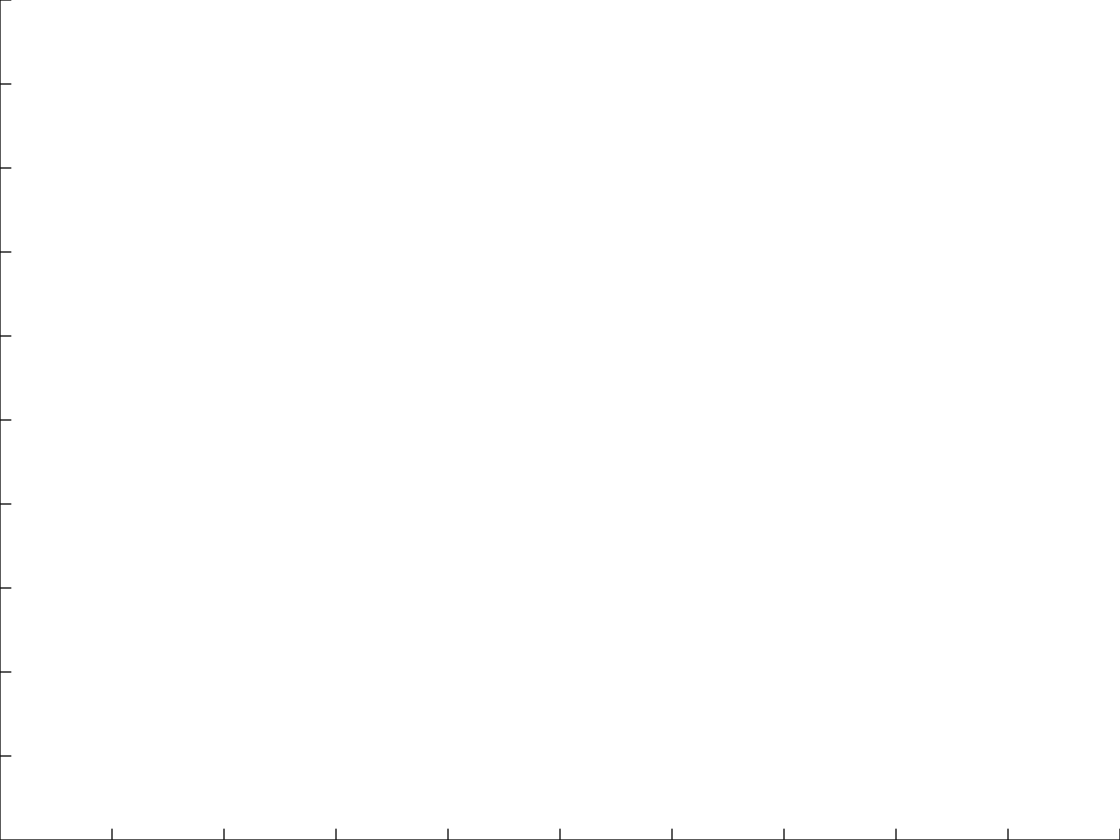

      *------------------------------------------------------------*
      *                                                            *
      *                      F I E L D   I I                       *
      *                                                            *
      *              Simulator for ultrasound systems              *
      *                                                            *
      *             Copyright by Joergen Arendt Jensen             *
      *    Version 3.30, April 5, 2021 (Matlab 2021a version)      *
      *                  Web-site: field-ii.dk                     *
      *                                                            *
      *     This is citationware. Note the terms and conditions    *
      *     for use on the web-site at:                            *
      *               field-ii.dk/?copyright.html                  *
      *  It is illegal to use this program, if the rules in the    *
      *  copyright statement is no

field_init()

wvl2m = Trans.spacingMm/Trans.spacing * 1e-3;

f0=Trans.frequency*1e6; % Transducer center frequency [Hz]
% fs=Receive(1).decimSampleRate*1e6; % Sampling frequency [Hz]
fs=100*1e6; % Sampling frequency [Hz]

c=1480; % Speed of sound [m/s]
lambda=c/f0; % Wave length [m]
width=Trans.elementWidth*wvl2m * scaleby; % Width of element
element_height=Trans.elevationApertureMm * 1e-3; % Height of element [m]
elevational_focus = Trans.elevationFocusMm / 1000;
kerf= (Trans.spacing - Trans.elementWidth)*wvl2m * scaleby; % Kerf [m]

Trans.spacingMm = (kerf + width)*1000;
Trans.elementWidth = width / wvl2m;
Trans.spacing = (kerf + width) / wvl2m;
Trans.numelements = ceil(128/scaleby);

focus=[0 0 8]/1000; % Fixed focal point [m]
N_elements=Trans.numelements; % Number of elements in the transducer


% N_active=15; % Active elements in the transducer

% Set the sampling frequency
set_sampling(fs);


% Generate aperture for emission
emit_aperture = xdc_focused_array(N_elements, width, element_height, kerf, elevational_focus, 1, 10, focus);

% Set the impulse response and excitation of the emit aperture

dt_trans = 1/(250e6);
ts_trans = 0:dt_trans:(dt_trans * (length(Trans.IR2wy)-1));
trans_emmit = hilbert(Trans.IR2wy);
trans_fft = fftshift(fft(trans_emmit));
freqs = 250e6/length(Trans.IR2wy) *((-length(Trans.IR2wy)/2) : (length(Trans.IR2wy)/2 -1));

dt = 1/fs;
ts_new = 0:dt:(dt_trans * (length(Trans.IR2wy)-1));
excitation = interp1(ts_trans,Trans.IR2wy,ts_new);

if ~mod(length(excitation),2)
    excitation = [excitation 0];
end

impulse_response=circshift([1 zeros(1,length(excitation)-1)],(length(excitation)-1)/2);
% impulse_response=impulse_response.*hanning(max(size(impulse_response)))';
xdc_impulse(emit_aperture, impulse_response);
% excitation=sin(2*pi*f0*(0:1/fs:2/f0));
xdc_excitation(emit_aperture, excitation);


% Generate aperture for reception
receive_aperture = xdc_focused_array(N_elements, width, element_height, kerf, elevational_focus, 1, 10, focus);
% Set the impulse response for the receive aperture
xdc_impulse(receive_aperture, impulse_response);



phantom_bounds = [8 1]/1000; %x,y bounds
smallest_lambda = c / (Trans.Bandwidth(2)*1e6);
xs = linspace(-phantom_bounds(1),phantom_bounds(1),ceil(2*phantom_bounds(1)/(smallest_lambda/5)));
ys = linspace(-phantom_bounds(2),phantom_bounds(2),ceil(2*phantom_bounds(2)/(smallest_lambda/5)));
[X,Y] = meshgrid(xs,ys);
Z = ones(size(X))*8/1000;
positions = [reshape(X,[],1) reshape(Y,[],1) reshape(Z,[],1)];
[len,~] = size(positions);
amp = ones(len,1);


[v,t] = calc_scat_all(emit_aperture,receive_aperture,positions,amp,1);

   0.0 % performed (roughly  14 hours,  4 minutes 14 seconds remaining)
   0.0 % performed (roughly  12 hours, 50 minutes 43 seconds remaining)
   0.0 % performed (roughly  12 hours, 39 minutes 36 seconds remaining)
   0.1 % performed (roughly  12 hours, 34 minutes  7 seconds remaining)
   0.1 % performed (roughly  12 hours, 37 minutes 14 seconds remaining)
Calculation will take roughly  12 hours, 37 minutes  7 seconds to complete                          
   0.1 % performed (roughly  12 hours, 39 minutes 18 seconds remaining)
   0.1 % performed (roughly  12 hours, 36 minutes  7 seconds remaining)
   0.1 % performed (roughly  12 hours, 37 minutes 45 seconds remaining)



[tpoints,~] = size(v);
IRM = zeros(Trans.numelements,Trans.numelements,tpoints);
for i=1:Trans.numelements
    js = (i-1)*Trans.numelements + (1:Trans.numelements);
    IRM(i,:,:) = hilbert(v(:,js)).';
end
dt = 1/fs;
tnew = t - 18*dt;

ts_short = tnew + ((0:dt:(dt*(length(IRM)-1))));

save('field_ii_l2214_scaleonethird.mat','IRM','t','tnew','fs','dt','excitation','impulse_response','Trans')


% dt = 1/fs;
% tsprior = 0:dt:t;
% tsprior = tsprior(1:end-1);
% [len,~] =size(v); 
% ts_after = t:dt:(t+dt*len);
% ts_after = ts_after(1:end-1);
% totalts = [tsprior ts_after];

% vt = [zeros(length(tsprior),128*128) ;v];
% IRM = zeros(128,128,length(totalts));
% for i=1:128
%     js = (i-1)*128 + (1:128);
%     IRM(i,:,:) = hilbert(vt(:,js)).';
% end
% 
% % im = find(totalts>1.12e-7,1,'first');
% % IRM_t = IRM(:,:,im:end);
% % totalts_t = totalts(1:end-im);
% 

% save IRM_l2214twothirds_5divs.mat IRM totalts Trans c fs xs t v
% % load IRM_l2214nokerf_5divs.mat

% IRM = IRM / max(max(max(abs(IRM))));
% shift = ceil((0.2*2/(1000*1480))/dt);
% IRM_shift = zeros(size(IRM));
% IRM_shift(:,:,shift:end) = IRM(:,:,1:end-shift+1);

% recievefnums = 1:1:6;
% labels = arrayfun(@(i) num2str(recievefnums(i)),1:length(recievefnums),'UniformOutput',false);
% 
% RM = FMCtoFocused_frequency(IRM_shift,1.48,fs*1e-6,Trans,8,6,'a_shrink');
% [das_data,xs,zs] = das(RM,1.48,Trans,fs*1e-6,8,12,'a_shrink');

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 2 workers.


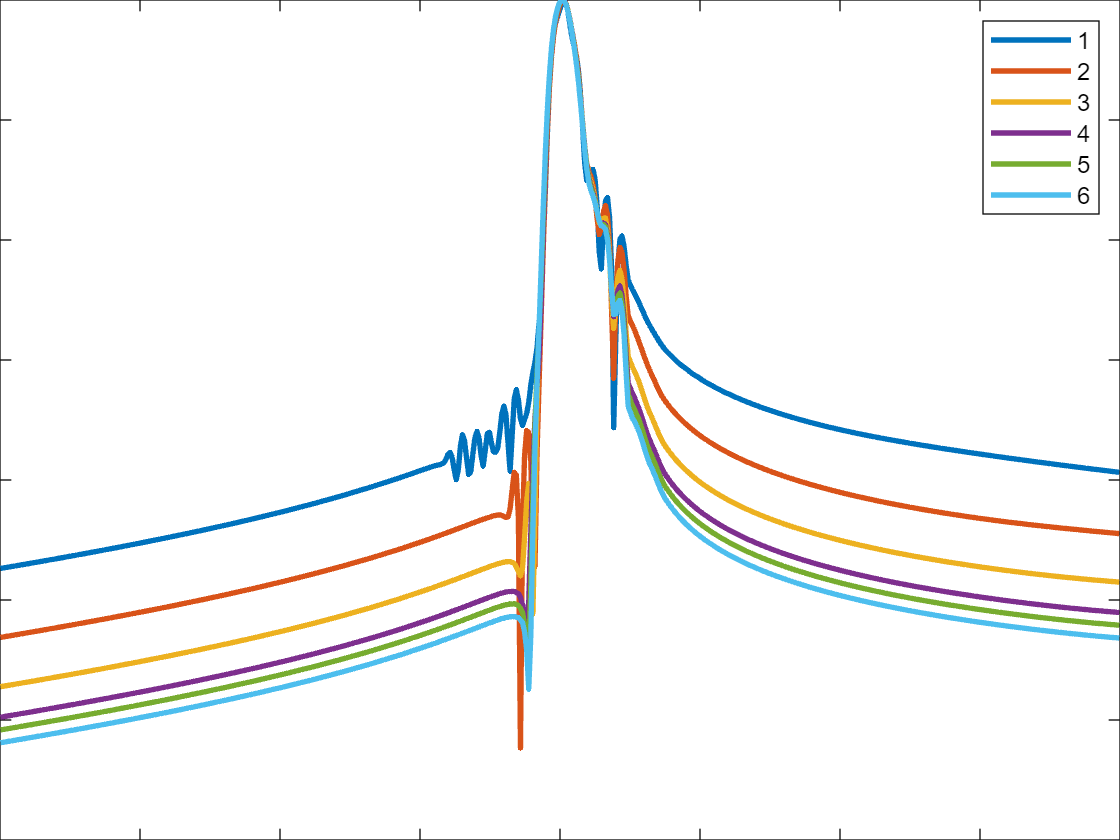

% aveline = zeros(length(recievefnums),length(zs));
% for i = 1:length(recievefnums)
%     fnum = recievefnums(i);
%     [das_data,xs,zs] = das(RM,1.48,Trans,fs*1e-6,8,fnum,'a_shrink');
%     bmode = 20*log10(abs(das_data).' + 1e-8) - max(max(20*log10(abs(das_data).' + 1e-8)));
% %     imagesc(xs,zs,bmode)
% %     colormap gray
%     aveline(i,:) = mean(bmode(:,64 + (-20:20)),2) - max(mean(bmode(:,64 + (-20:20)),2));
% end
% plot(zs((zs>6)&(zs<10)),aveline(:,(zs>6)&(zs<10)),'LineWidth',2)
% legend(labels)
% title('Mean axial profile, transmission f/6, various recieve')
% xlabel('z (mm)')
% ylabel('dB')

% 
% planewave = sum(IRM_shift,1);
% planewave = planewave / max(max(abs(planewave)));
% planewave_sa = planewave /(10^(6/20)-1);
% fnum = 6;
% RM = FMCtoFocused_frequency(IRM_shift,1.48,fs*1e-6,Trans,8,fnum,'a_shrink');
% RM = RM / max(max(max(abs(RM))));

% plot(totalts*1000*1480/2,squeeze(real(IRM_shift(64,64,:))))

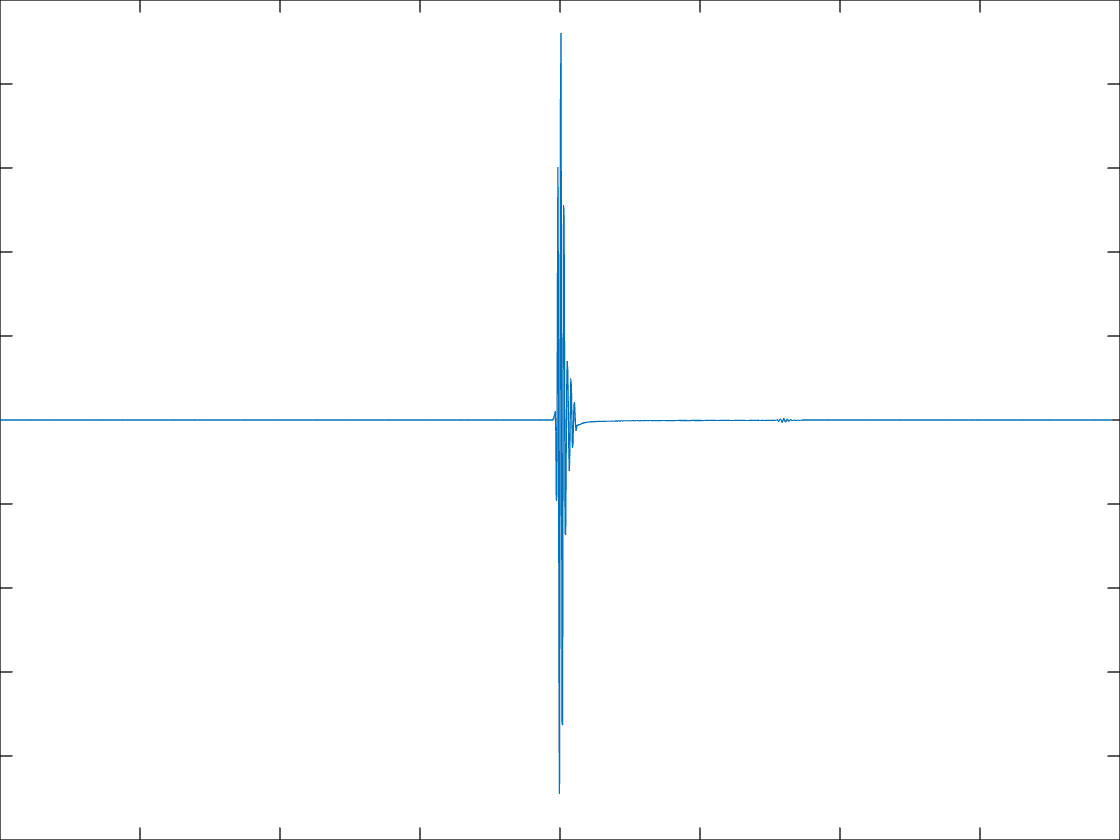

% IRM_sa = IRM_shift + planewave_sa;
% IRM_sa = IRM_sa / max(max(max(abs(IRM_sa))));

% % imagesc(xs*1000,totalts*1000*1480/2,squeeze(abs(planewave)).')

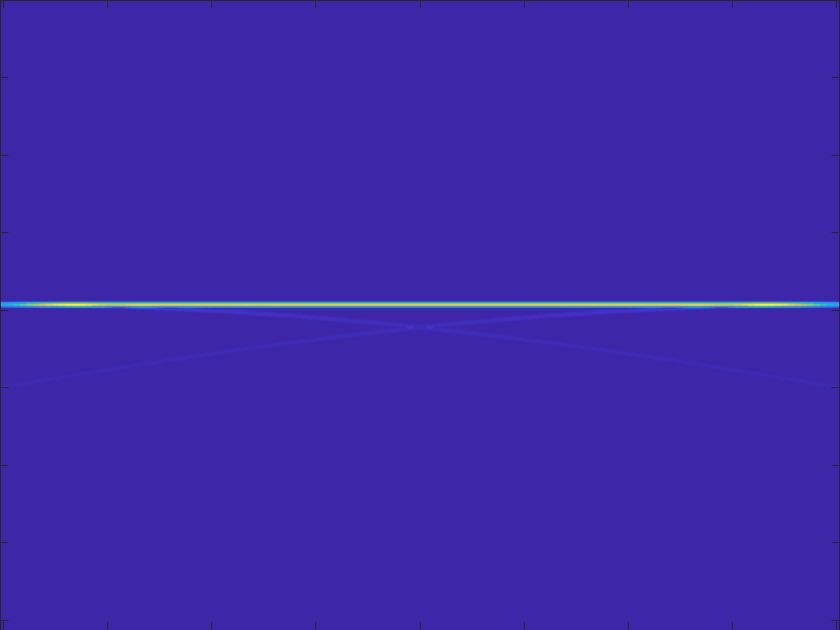

% i=64;
% bmode = squeeze(20*log10(abs(IRM_sa(i,:,:)) + 10e-4)).';
% imagesc(xs*1000,totalts*1000*1480/2,bmode)
% colormap gray

% colorbar
% hold on

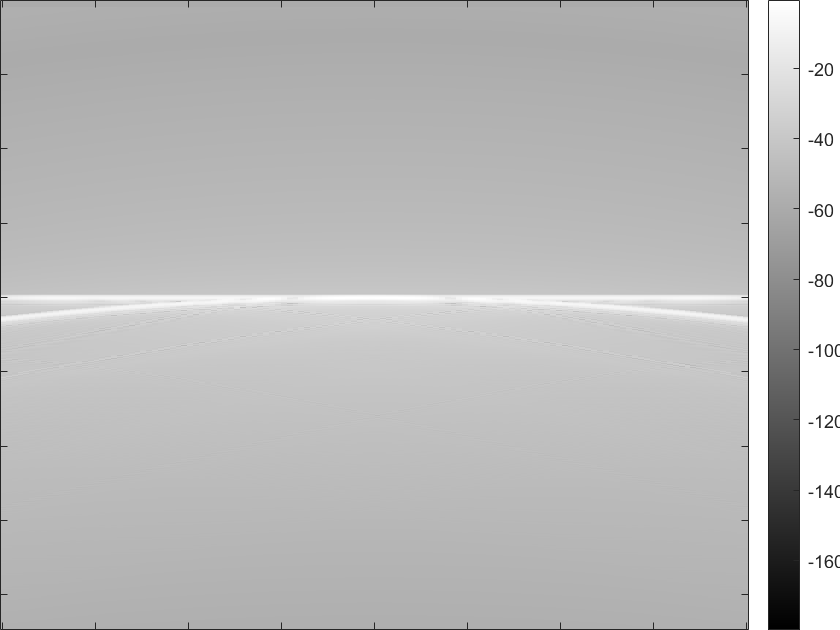

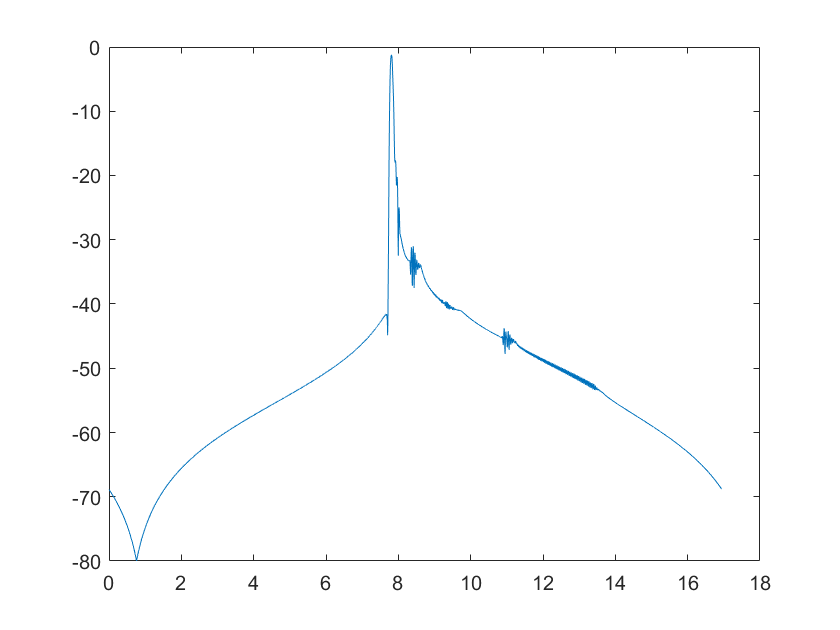

% figure()
% plot(totalts*1000*1480/2,squeeze(20*log10(abs(IRM_sa(64,64,:))+10^-4)))